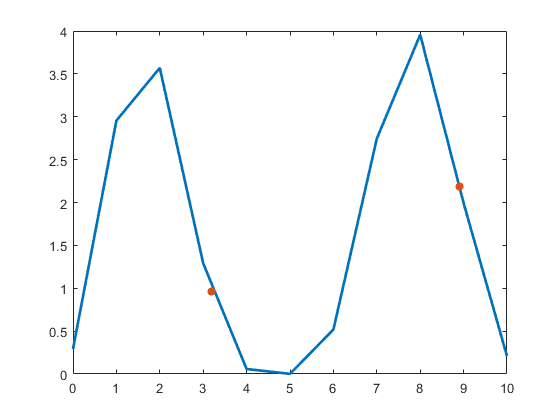

clc,clear,close all
x_total = 0:10;
y_total = [0.29192658 2.95514510 3.56969634 1.29077814 0.05830675 0.00162701 0.51871583 2.74494186 3.95707540  1.99386861  0.20787205];

x = [3.2,8.9];
y = zeros(1,length(x));

for i = 1 : length(x)
    xx = x(i);
    dif = abs(x_total - xx);
    [~,index] = mink(dif,3);
    index = sort(index);
    x_train = x_total(index);
    y_train = y_total(index);
    y(i) = lagrange(xx,x_train,y_train);
end


plot(x_total,y_total,x,y,'*',"LineWidth",2)